# `Tree Search for Path Planning`

RRT (Rapidly-exploring Random Tree)

`State Space Vehicle Model`

`Brian Lesko`

`Masters of Mechanical Engineering`

`Ohio State University `

`April 12, 2023`

`Dr. Levent Guvenc`

`Originally a Matlab and Simulink mardown file`

`By Brian Lesko, Graduate researcher and Teaching associate, Masters of mechanical engineering student`

`Inspired by Robust Controls of Mechatronic Systems, by Dr. Levent Guvenc`

# `Contents`

- `Contents`

- `Introduction `

- `Background`

- `Conclusion`

- `Functions`

# `Introduction`

`    Path planning models are critical components in vehicle control systems and mobile robotics. These algorithms enable autonomous systems to find optimal or near-optimal routes from a starting point to a destination, while avoiding obstacles and adhering to certain constraints. Path planning models can have variations with RRT being a popular base choice. RRT is a sampling-based motion planning algorithm that efficiently explores the configuration space of the robot. It builds a tree structure that rapidly expands towards unexplored regions, which makes it particularly suitable for high-dimensional and complex environments. RRT* is an extension of RRT that improves the optimality of the solution by continuously refining the tree structure. Another variation on the search algorithm is to set constrains. One example is the Dubins Car model, a widely-used method for modeling the constraints of non-holonomic systems, such as cars with limited turning radius. This model simplifies the path planning problem while maintaining crucial constraints, making it computationally efficient. Alternative models include the Reeds-Shepp Car and the Lattice model. A second complciation is the implementation of occupancy maps, which are a common method for representing the environment in mobile robotics. They provide a discrete representation of the environment's occupied and free spaces, making it easier to integrate with path planning algorithms. By using occupancy maps, these algorithms can efficiently navigate around obstacles and find feasible paths.`

`    In the following demonstration, the methods discussed will be employed to showcase their effectiveness in path planning and obstacle avoidance for a mobile robotics system. RRT and will be used to plan a path with the Dubins Car model to simulate the constraints of a non-holonomic system all while occupancy maps will be utilized to represent the environment, providing a discrete representation of occupied and free spaces.`

# Background 

[https://www.mathworks.com/help/nav/ug/plan-mobile-robot-paths-using-rrt.html](https://www.mathworks.com/help/nav/ug/plan-mobile-robot-paths-using-rrt.html)

# Setup Process

clc; clear; close all;

# Import an occupancy map

load("office_area_gridmap.mat", "occGrid")

# Determine Start and Goal Positions 

start = [-1.0, 0.0, -pi];
goal = [14, -2.25, 0];

## Visualize

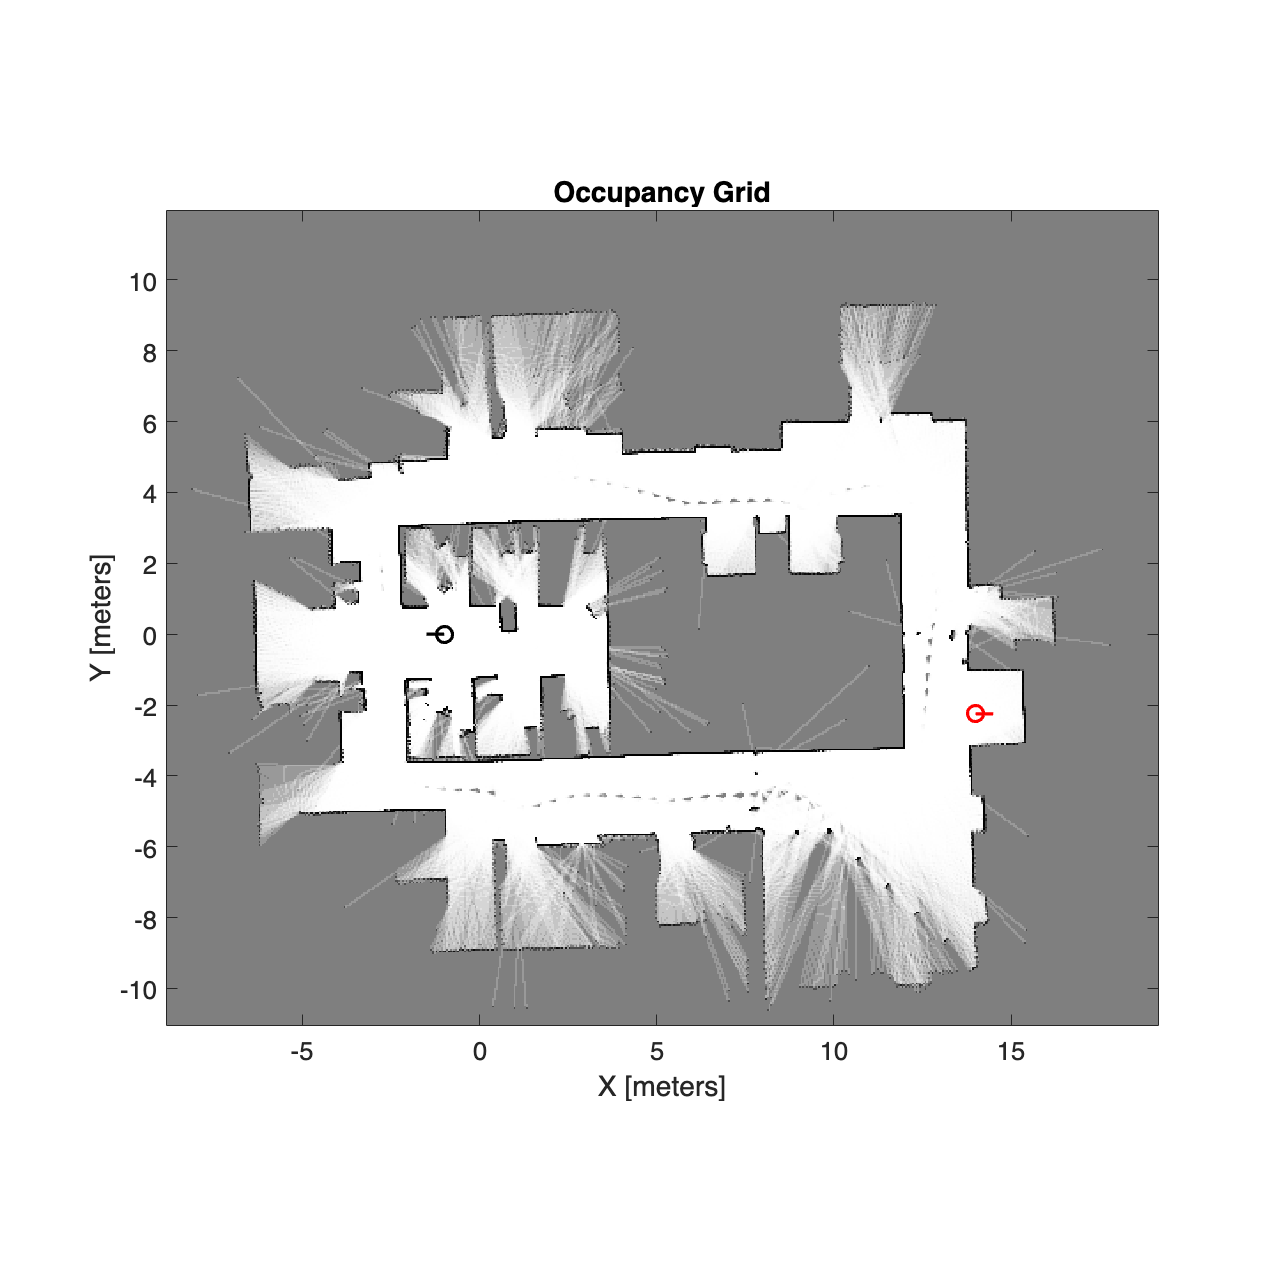

plt =   1×2 Line array:

    Line    Line


figure()
plt = plotMap(occGrid,start,goal)

# Define the Vehicle Model constraints 

Dubins State Space Model

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];
ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = .4;

# Path Planning Parameters

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;
planner = plannerRRT(ss, stateValidator);
planner.MaxConnectionDistance = 2;
planner.MaxIterations = 30000;
planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

# Run the path generator 

rng(0,'twister')
[pthObj, solnInfo] = plan(planner, start, goal);

# Plot the Path

Show the occupancy map. Plot the search tree from the `solnInfo`. Interpolate and overlay the final path.

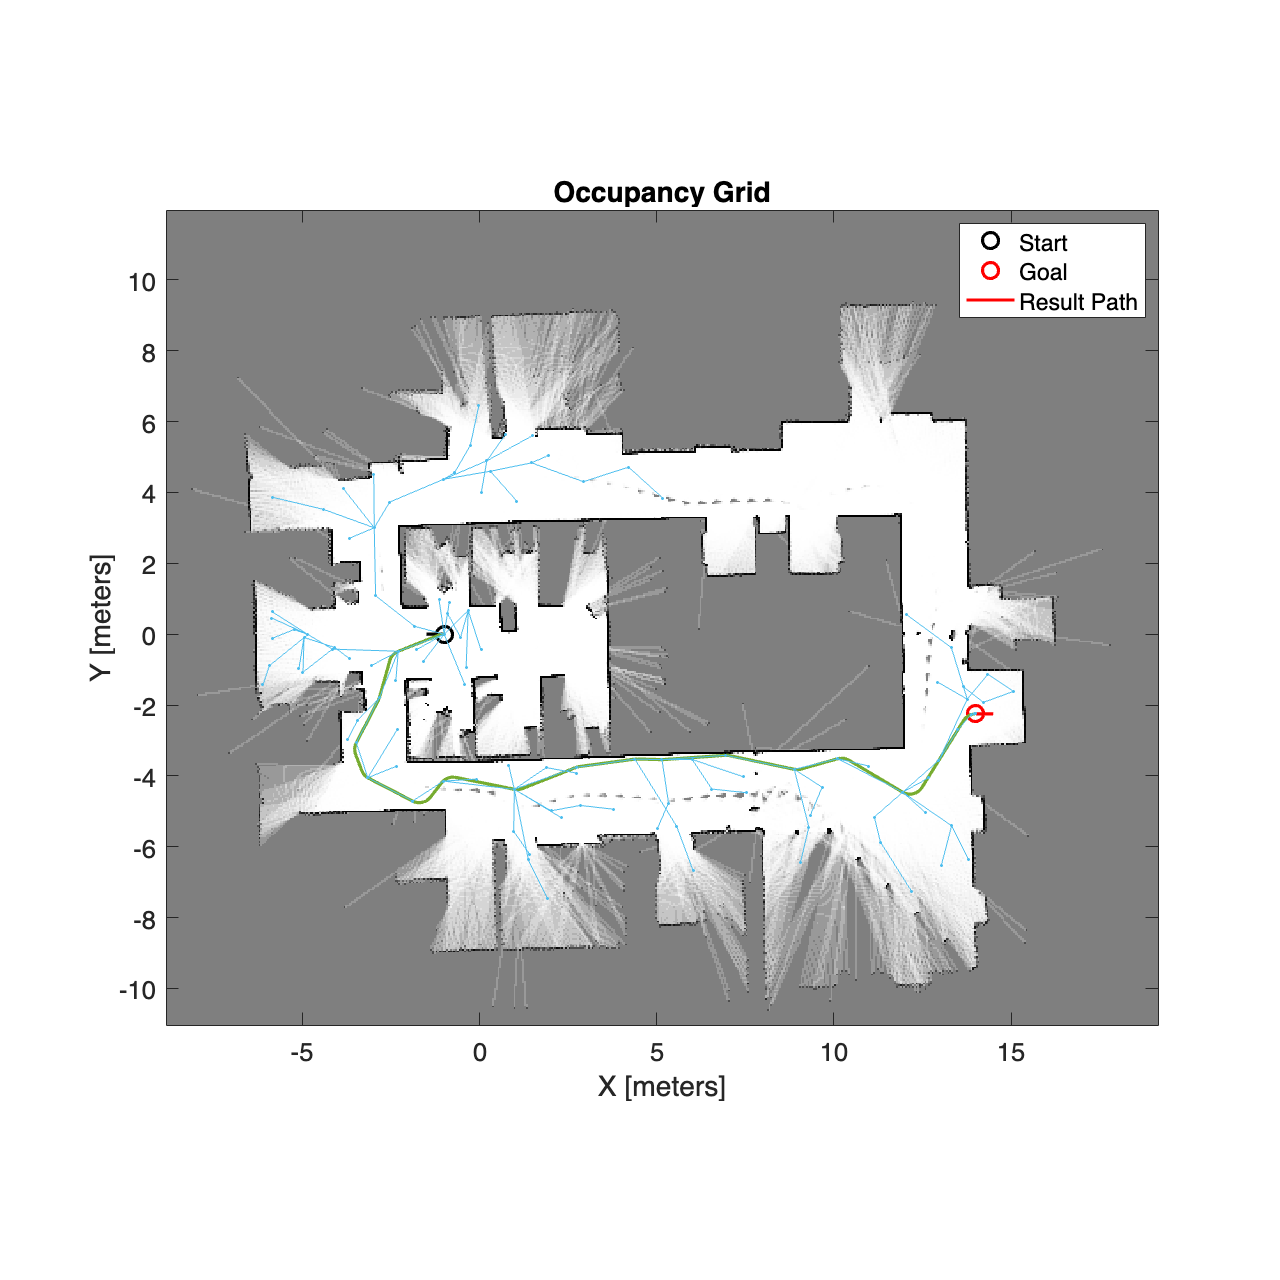

figure()
plotMap(occGrid,start,goal);
plotResult(pthObj, solnInfo);
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-'); 
legend('Start','Goal','','Result Path')

# Effect of minimum turning radius on RRT					

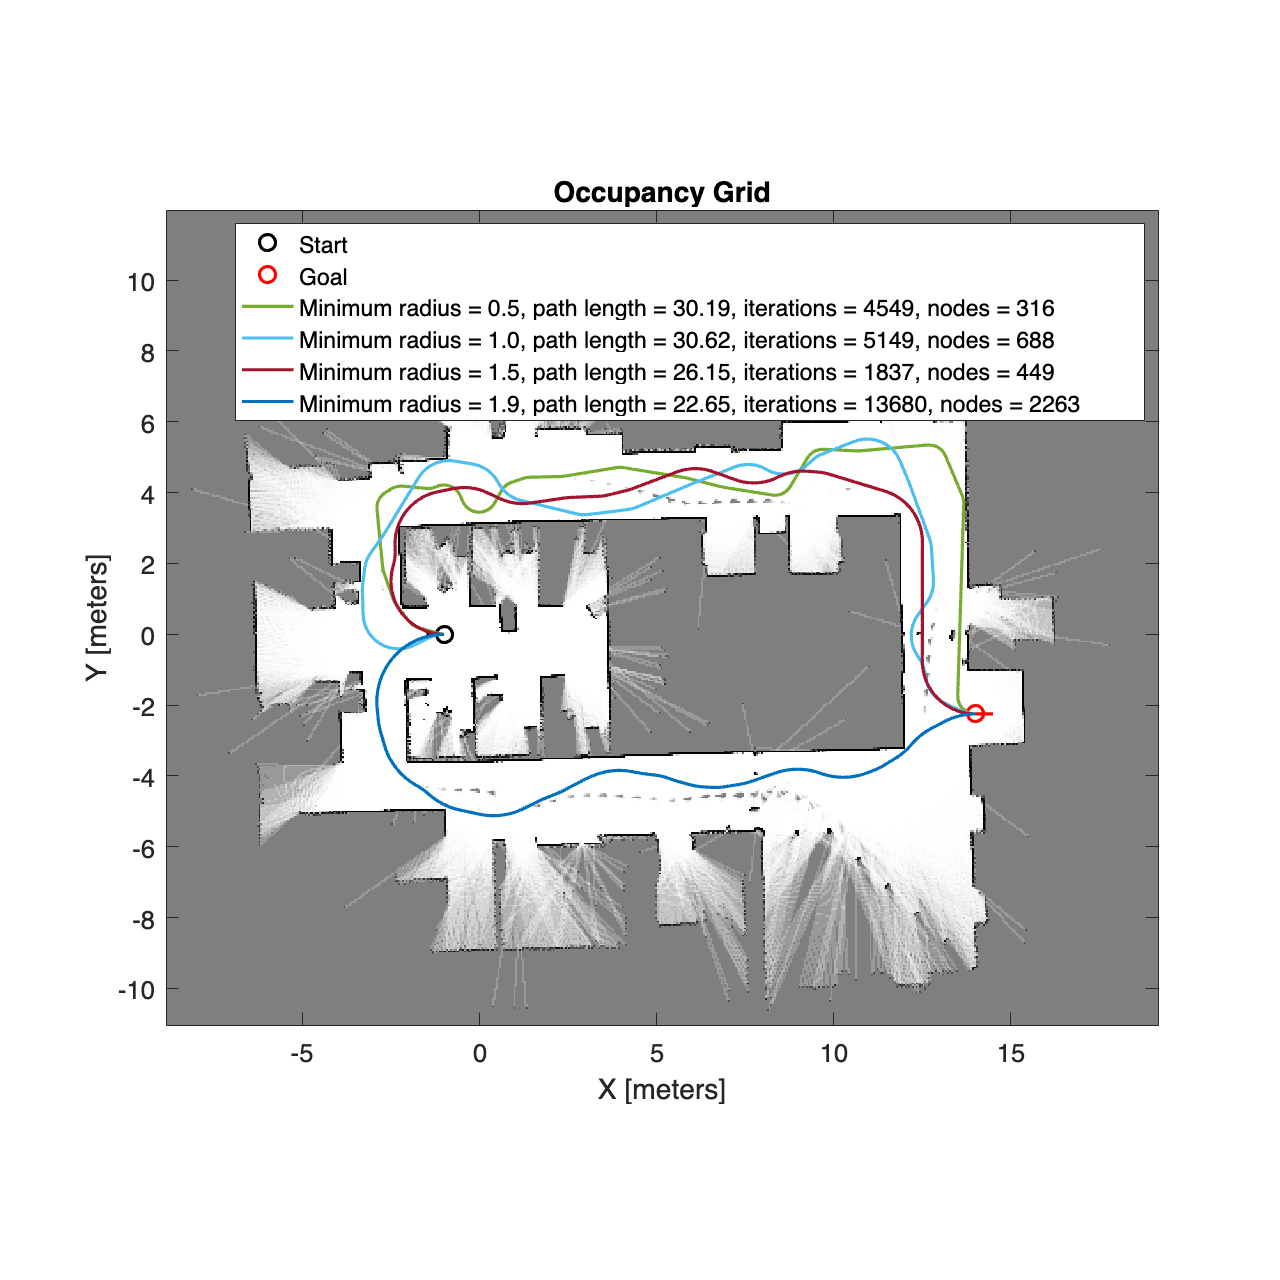

radii = [0.5,1,1.5,1.9];
plot = 1;
[lengths, iterations, nodeCounts] = varyRadii(radii,plot,occGrid,start,goal);

`As the turning radius minimum increases, the path length decreased while the iterations and nodes increased. For this occupancy map, a turning radius of >1.9 results in no solvable paths to the goal because of the narrow hallways.`

# Effect of Maximum Connection Distance

with radius = 1, maximum connection distances ( 0.5, 1, 1.5, 2) 		

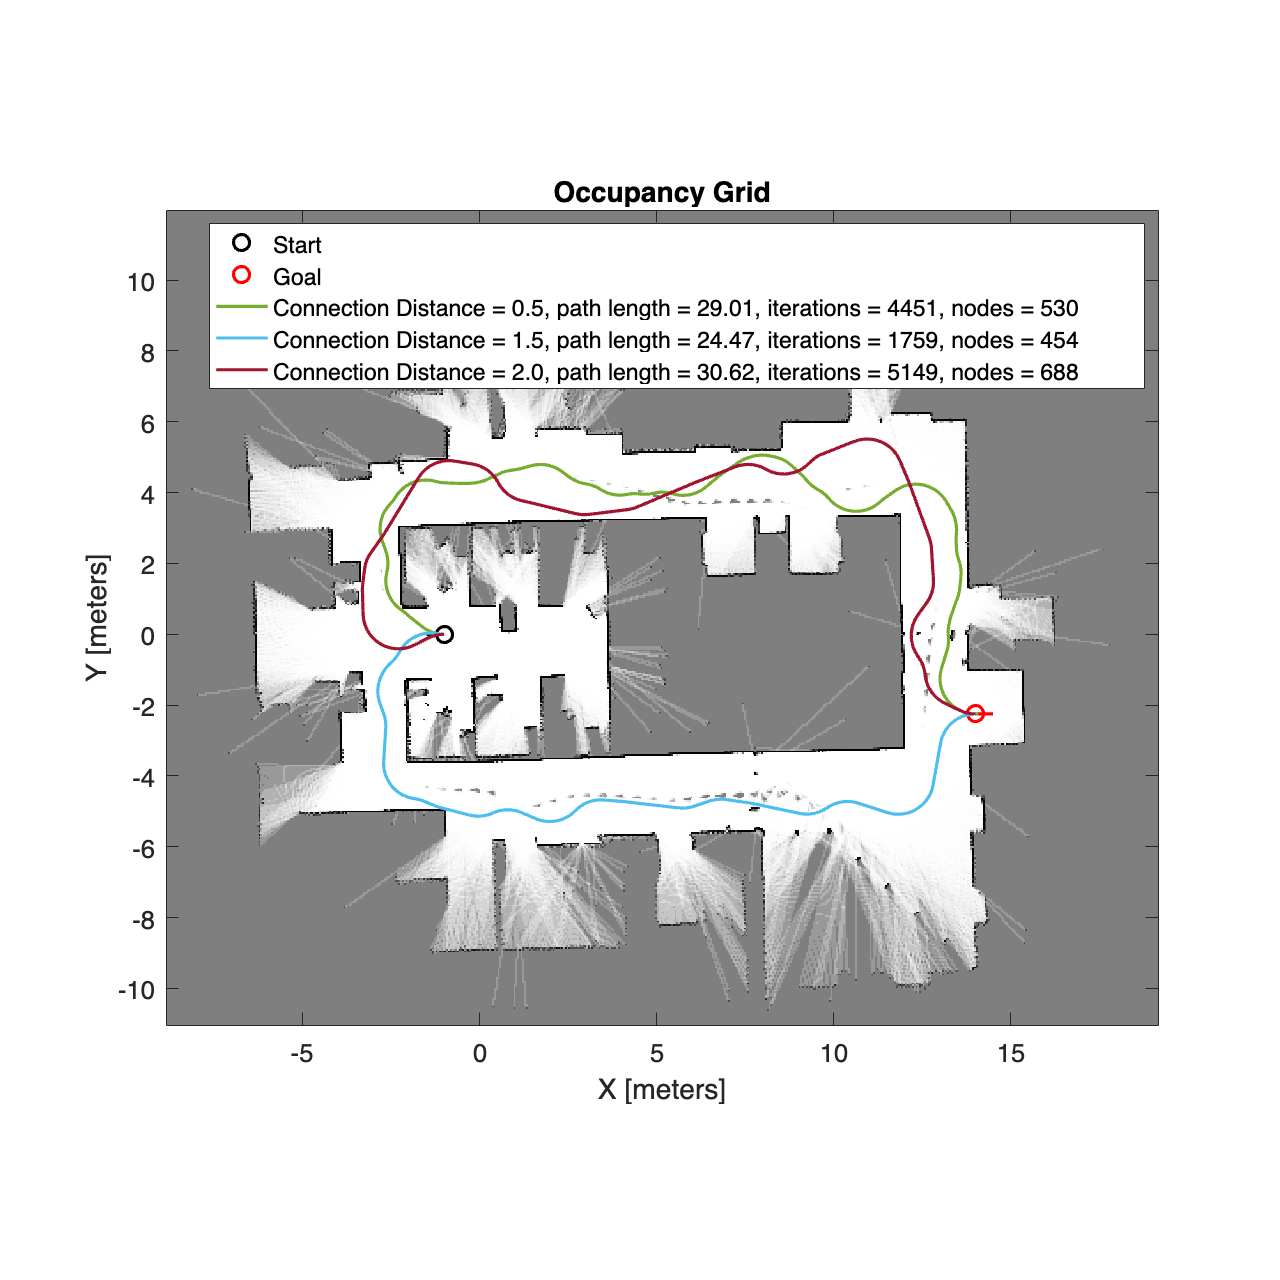

connectionDistances = [.5,1.5,2];
plot = 1;
[lengths, iterations, nodeCounts] = varyConnectionDistance(connectionDistances,plot,occGrid,start,goal);

`The Number of nodes and iterations is primarily dependant on if the path is generated on the top or the botton, but the nodes and interations seem to increase as the connection distance increases`

# `Create an Occupancy Map from an image`

`Following the example from: `[`https://www.mathworks.com/help/nav/ref/binaryoccupancymap.html#buvr49e.`](https://www.mathworks.com/help/nav/ref/binaryoccupancymap.html#buvr49e.)

`Create a binary occupancy map `

`Note to self: map = binaryOccupancyMap(`[`p`](https://www.mathworks.com/help/nav/ref/binaryoccupancymap.html#mw_70d54208-7361-4bec-8477-d956e69430fe)`)` creates a grid from the values in matrix `p, possibly useful for the robotics repository`

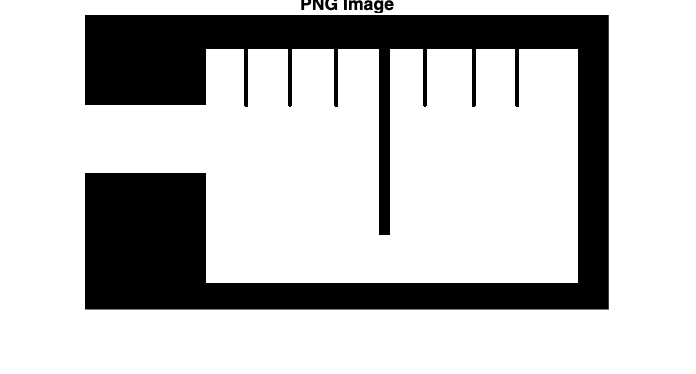

close all
image = imread('plot.png');
imshow('plot.png'), title('PNG Image')

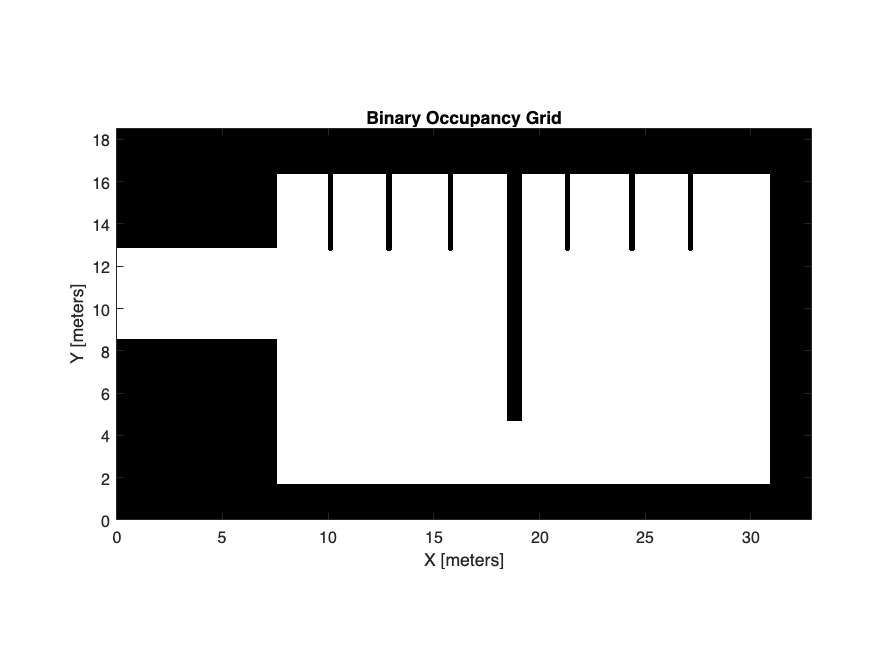

% Convert the RGB image to grayscale
gray_image = rgb2gray(image);

% Convert the grayscale image to a binary image
binary_image = imbinarize(gray_image);

% Invert the binary image
inverted_binary_image = imcomplement(binary_image);

% Create the map
map = binaryOccupancyMap(inverted_binary_image,20); % 20 is the resolution to scale properly
figure()
show(map)

# Find the start and goal positions 

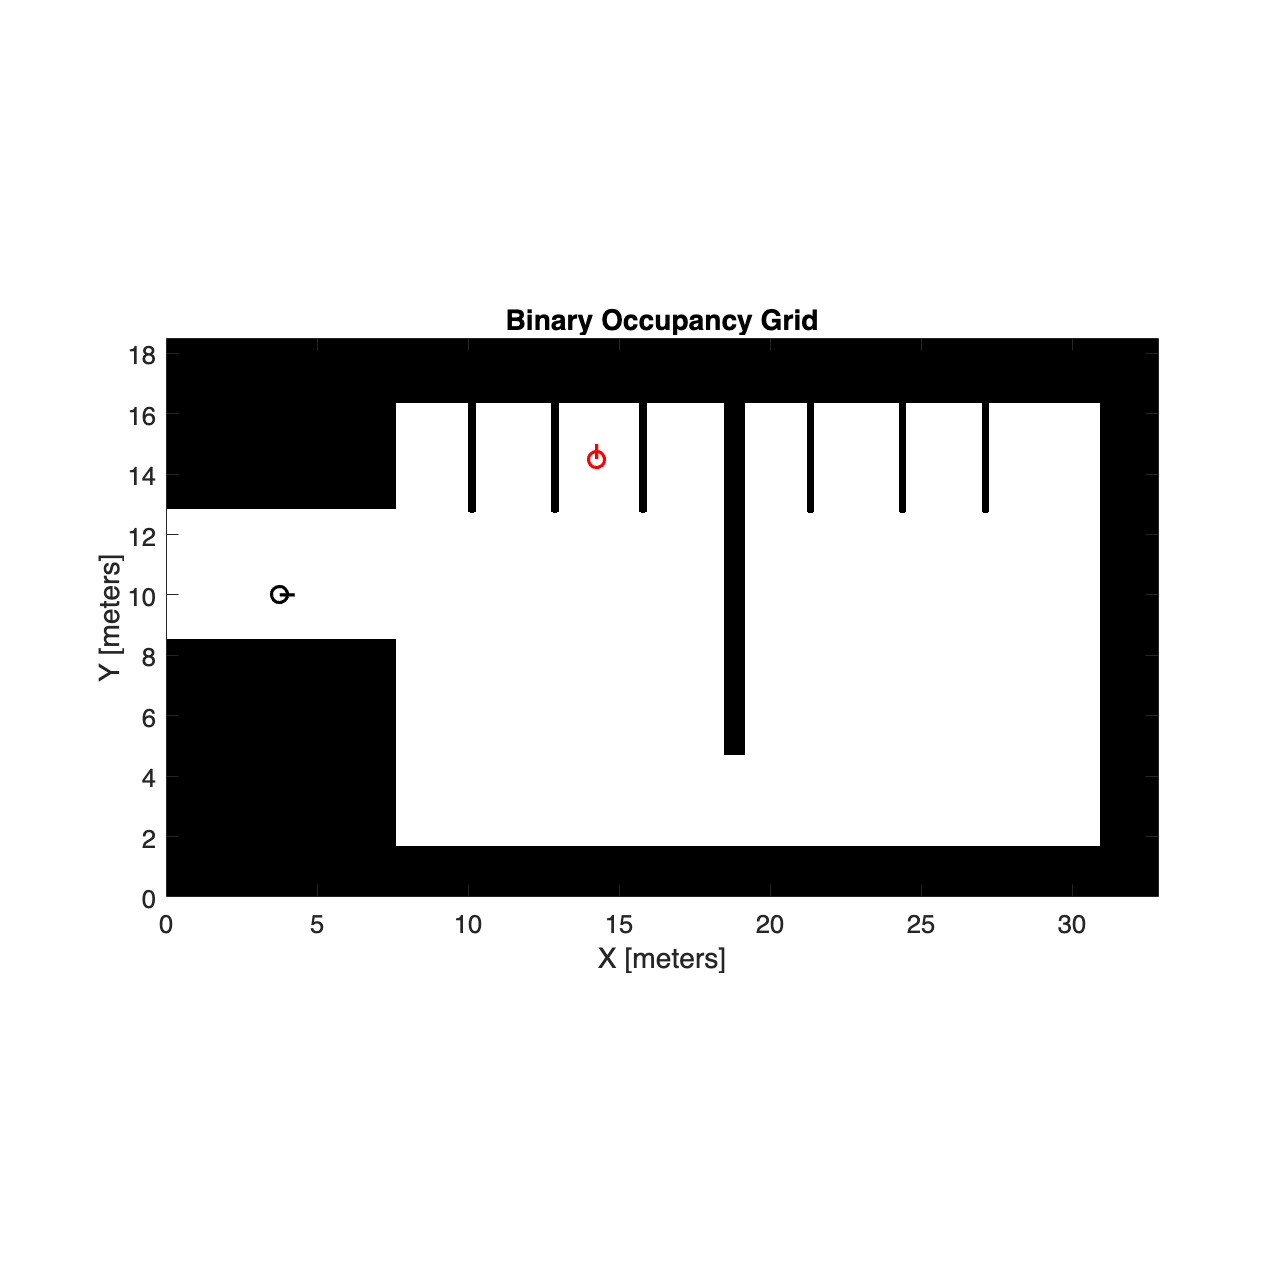

ans =   1×2 Line array:

    Line    Line


start = [3.75, 10, 0];
goal = [14.25, 14.5, pi/2];
plotMap(map,start,goal)

# RRT with the "Garage" occupancy map

ans =   Line with properties:

              Color: [0.4660 0.6740 0.1880]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [3.7500 4.0380 4.3260 4.6139 4.9018 5.1857 5.4680 5.7487 6.0294 6.3345 6.6353 6.9306 7.2193 7.5002 7.8112 8.1090 8.3921 8.6591 8.9086 9.1393 9.3675 9.5709 9.7480 9.8980 10.0198 10.1047 10.2042 10.3239 10.4635 10.6223 10.8404 … ]
              YData: [10 9.9927 9.9819 9.9711 9.9603 9.9415 9.9066 9.8607 9.8144 9.7543 9.6753 9.5778 9.4621 9.3287 9.1547 8.9590 8.7425 8.5065 8.2521 7.9805 7.6673 7.3374 6.9927 6.6353 6.2674 5.9503 5.6374 5.3318 5.0347 4.7473 4.4127 4.0966 3.8009 … ]

  Show all 

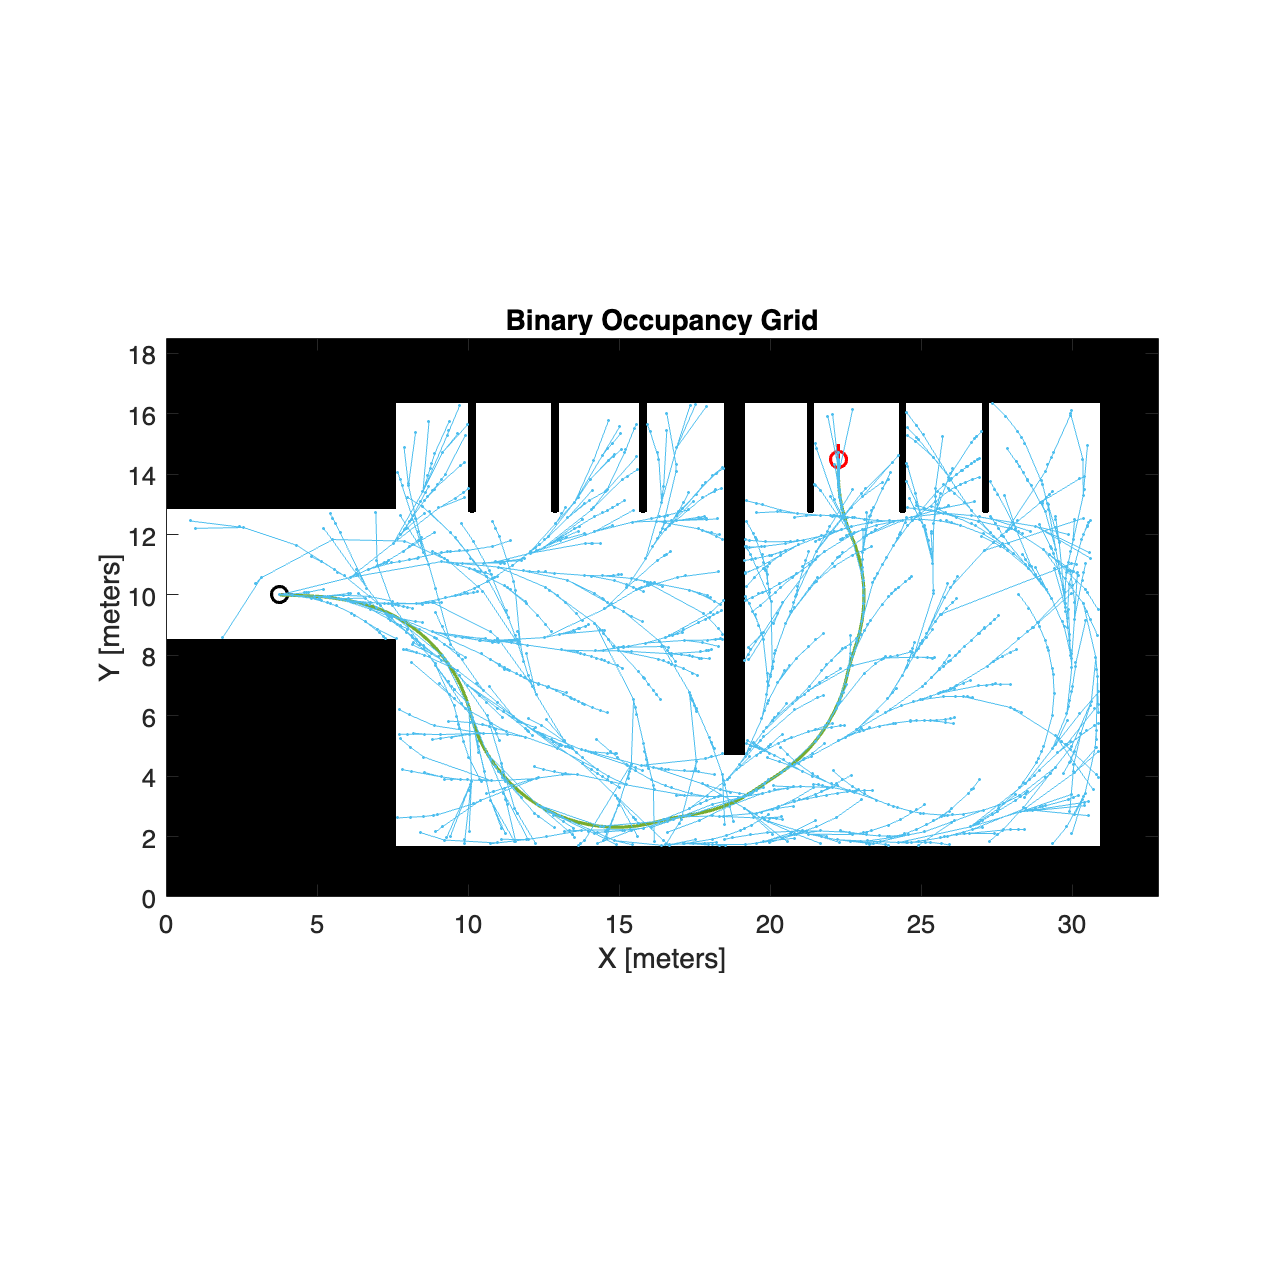

minTurningRadius = 5;
maxConnectionDistance = 2;
goal = [22.25, 14.5, pi/2];
constrainedRRT(minTurningRadius,maxConnectionDistance,map,start,goal);

# RRT* with the "Garage" occupancy map

But with RRT*

ans =   Line with properties:

              Color: [0.4660 0.6740 0.1880]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [3.7500 3.7944 3.8389 3.8833 3.9277 3.9721 4.0165 4.0609 4.1053 4.1496 4.1939 4.2381 4.2823 4.3265 4.3706 4.4147 4.4587 4.5027 4.5466 4.5904 4.6342 4.6779 4.7216 4.7651 4.8086 4.8520 4.8953 4.9385 4.9816 5.0247 5.0676 5.1104 … ]
              YData: [10 9.9998 9.9992 9.9982 9.9968 9.9951 9.9929 9.9903 9.9874 9.9840 9.9803 9.9761 9.9716 9.9667 9.9613 9.9556 9.9495 9.9430 9.9361 9.9289 9.9212 9.9131 9.9047 9.8959 9.8867 9.8771 9.8671 9.8567 9.8459 9.8348 9.8233 9.8114 9.7991 … ]

  Show all 

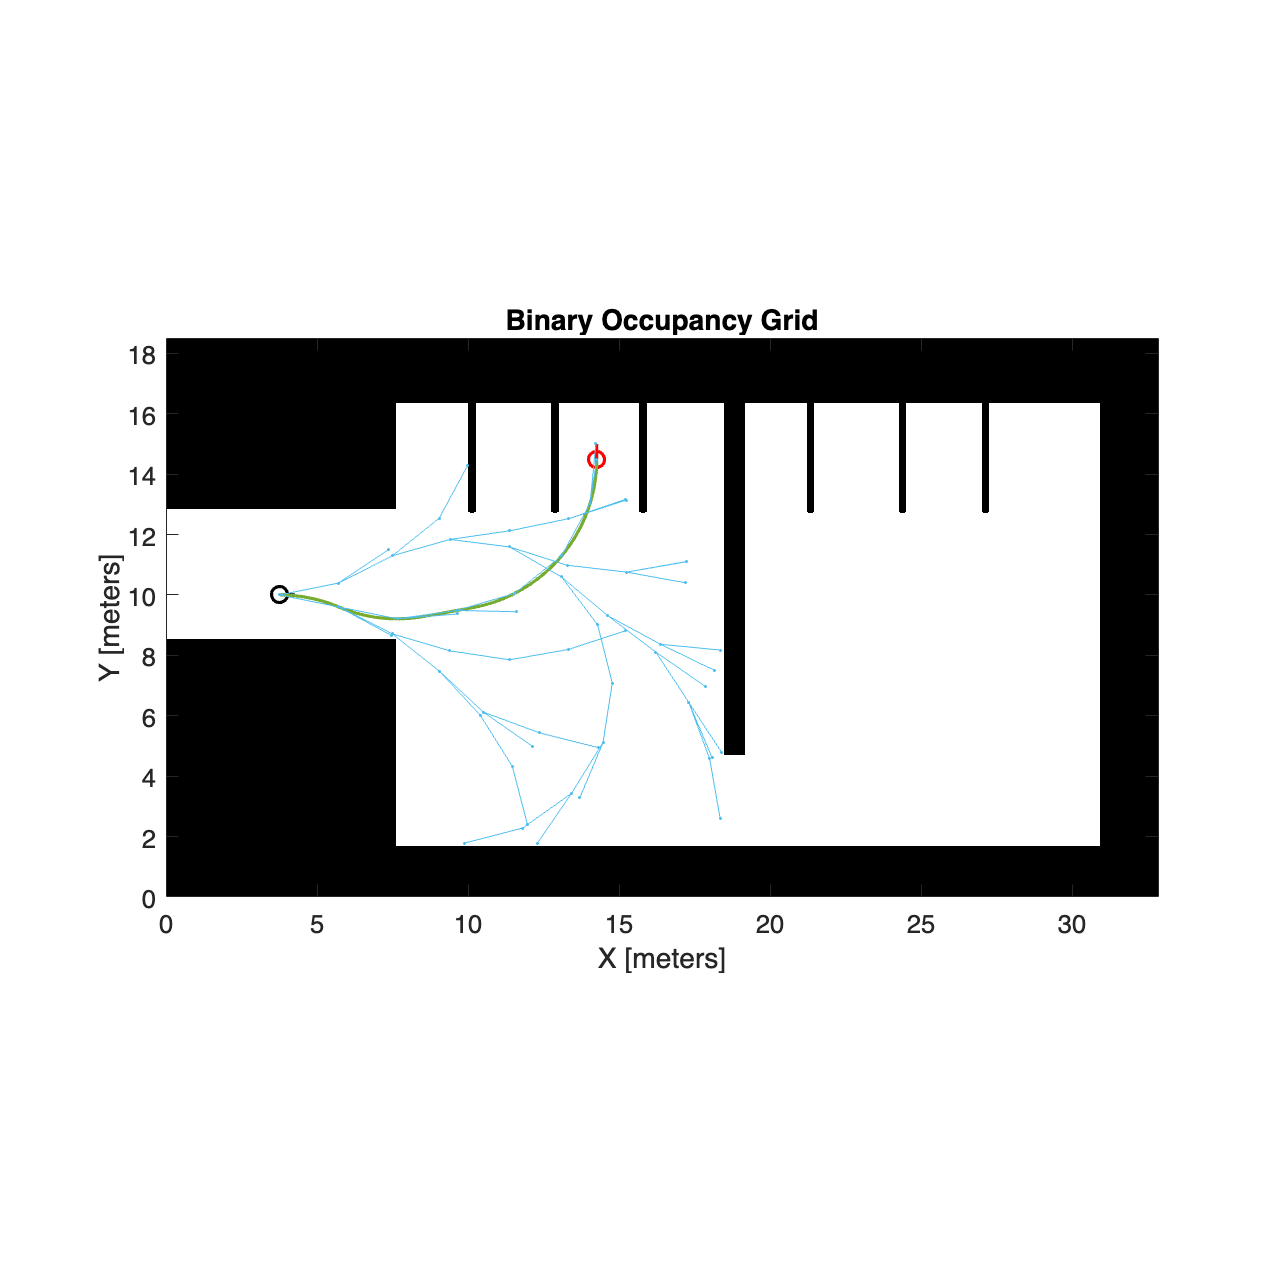

% set the minumum turning radius to 5 m. Set the maximum connection distance to 2m
minTurningRadius = 5;
maxConnectionDistance = 2;
goal = [14.25, 14.5, pi/2];
constrainedRRTStar(minTurningRadius,maxConnectionDistance,map,start,goal);

ans =   Line with properties:

              Color: [0.4660 0.6740 0.1880]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [3.7500 3.8500 3.9499 4.0498 4.1496 4.2492 4.3486 4.4477 4.5466 4.6451 4.7433 4.8411 4.9385 5.0354 5.1318 5.2276 5.3228 5.4174 5.5114 5.6046 5.6971 5.7888 5.8797 5.9697 6.0590 6.1481 6.2373 6.3264 6.4155 6.5047 6.5938 6.6829 … ]
              YData: [10 9.9990 9.9960 9.9910 9.9840 9.9750 9.9640 9.9511 9.9361 9.9192 9.9003 9.8795 9.8567 9.8319 9.8053 9.7767 9.7462 9.7138 9.6795 9.6433 9.6053 9.5654 9.5238 9.4803 9.4352 9.3898 9.3445 9.2992 9.2539 9.2085 9.1632 9.1179 9.0725 … ]

  Show all 

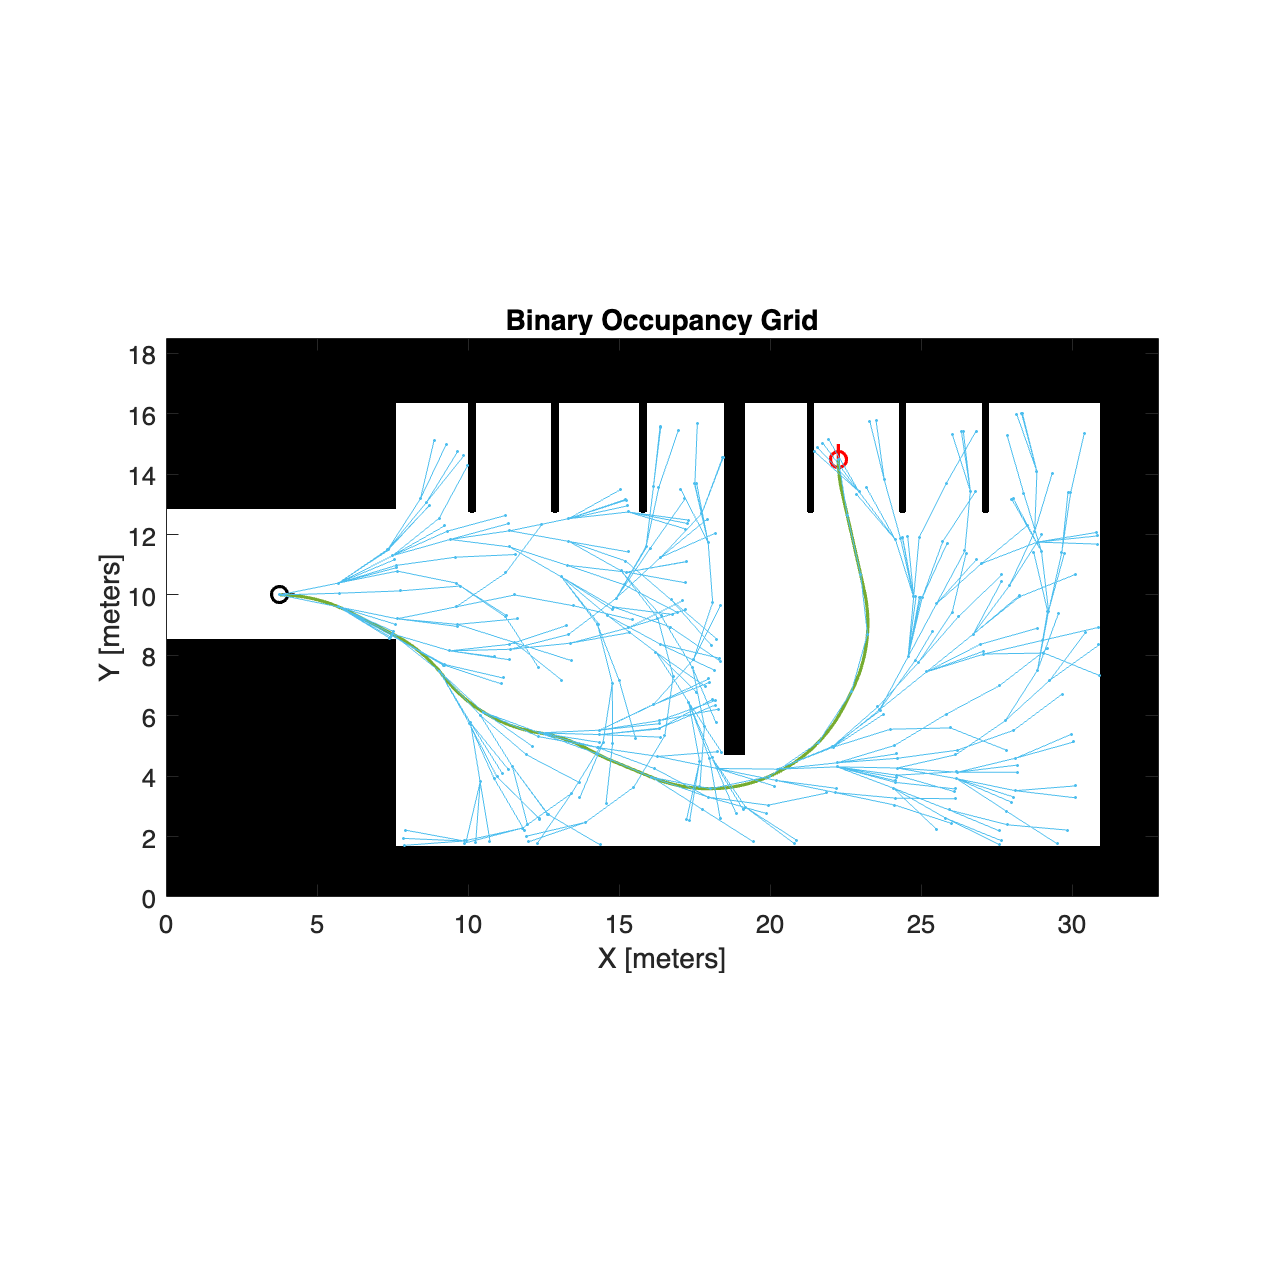

goal = [22.25, 14.5, pi/2];
constrainedRRTStar(minTurningRadius,maxConnectionDistance,map,start,goal);

`The limitations include not accounting for the width of the vehicle, the RRT* algorithm creates a smoother path`

# `Functions `

Plot Result Path and tree

function h = plotResult(pthObj, solnInfo)
    hold on

    % Search tree
    % plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-'); 
    
    % Interpolate and plot path
    interpolate(pthObj,300)
    h = plot(pthObj.States(:,1), pthObj.States(:,2), '-', 'LineWidth', 2);
end 

# `Plot occupancy map `

function h = plotMap(occGrid,start,goal)
    % occupancy grid
    show(occGrid)
    
    % Show the start and goal positions of the robot
    hold on
    h(1) = plot(start(1), start(2), 'ko','Linewidth',2,MarkerSize=10);
    h(2) = plot(goal(1), goal(2), 'ro','Linewidth',2,MarkerSize=10);
    
    % Show the start and goal headings
    r = 0.5;
    plot([start(1), start(1) + r*cos(start(3))], [start(2), start(2) + r*sin(start(3))], 'k-','Linewidth',2)
    plot([goal(1), goal(1) + r*cos(goal(3))], [goal(2), goal(2) + r*sin(goal(3))], 'r-','Linewidth',2)
    set(gcf, 'Position', [0 0 2500 2500])
    set(gca,'FontSize',16)
end 

# Vary the turning radius minimum 

function [lengths, iterations, nodeCounts] = varyRadii(radii,plot,occGrid,start,goal)
    loop = 1;
    % Plotting only
    if plot == 1
        handles = [];
        % Initialize a cell array to store legend entries
        legendEntries = cell(1, length(radii)+2);
        % Add 'Start' and 'Goal' to legendEntries
        legendEntries{1} = 'Start';
        legendEntries{2} = 'Goal';
    end 
    
    close all; figure()
    handles = plotMap(occGrid,start,goal);
    for radius = radii 
        pthObj = 0;
        solnInfo = 0;
    
        % input occGrid, radius 
        % Setup Model 
        bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];
        ss = stateSpaceDubins(bounds);
        ss.MinTurningRadius = radius; % what is changing every round
    
        % Setup RRT 
        stateValidator = validatorOccupancyMap(ss); 
        stateValidator.Map = occGrid;
        stateValidator.ValidationDistance = 0.05;
        planner = plannerRRT(ss, stateValidator);
        planner.MaxConnectionDistance = 2;
        planner.MaxIterations = 30000;
        planner.GoalReachedFcn = @exampleHelperCheckIfGoal;
    
        % Solve RRT
        rng(0,'twister')
        [pthObj, solnInfo] = plan(planner, start, goal);
    
        % Save Results 
        lengths(loop) = pthObj.pathLength; iterations(loop) = solnInfo.NumIterations; nodeCounts(loop) = solnInfo.NumNodes;
    
        % Plotting only
        if plot == 1
            % Create a legend entry
            legendEntries{loop+2} = sprintf('Minimum radius = %.1f, path length = %.2f, iterations = %d, nodes = %d',radius, lengths(loop), iterations(loop), nodeCounts(loop));
            % Plot Results
            hold on; 
            handles(loop + 2) = plotResult(pthObj, solnInfo); % Store the handle
        end 
    
        loop = loop + 1;
    end
    if plot == 1
        legend(handles,legendEntries); end 
end 

# Vary Connection Distance

function [lengths, iterations, nodeCounts] = varyConnectionDistance(connectionDistances,plot,occGrid,start,goal)
    loop = 1;
    % Plotting only
    if plot == 1
        handles = [];
        % Initialize a cell array to store legend entries
        legendEntries = cell(1, length(connectionDistances)+2);
        % Add 'Start' and 'Goal' to legendEntries
        legendEntries{1} = 'Start';
        legendEntries{2} = 'Goal';
    end 
    
    close all; figure()
    handles = plotMap(occGrid,start,goal);
    for connectionDistance = connectionDistances
        pthObj = 0;
        solnInfo = 0;
    
        % input occGrid, radius 
        % Setup Model 
        bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];
        ss = stateSpaceDubins(bounds);
        ss.MinTurningRadius = 1; % what is changing every round
    
        % Setup RRT 
        stateValidator = validatorOccupancyMap(ss); 
        stateValidator.Map = occGrid;
        stateValidator.ValidationDistance = 0.05;
        planner = plannerRRT(ss, stateValidator);
        planner.MaxConnectionDistance = connectionDistance;
        planner.MaxIterations = 30000;
        planner.GoalReachedFcn = @exampleHelperCheckIfGoal;
    
        % Solve RRT
        rng(0,'twister')
        [pthObj, solnInfo] = plan(planner, start, goal);
    
        % Save Results 
        lengths(loop) = pthObj.pathLength; iterations(loop) = solnInfo.NumIterations; nodeCounts(loop) = solnInfo.NumNodes;
    
        % Plotting only
        if plot == 1
            % Create a legend entry
            legendEntries{loop+2} = sprintf('Connection Distance = %.1f, path length = %.2f, iterations = %d, nodes = %d',connectionDistance, lengths(loop), iterations(loop), nodeCounts(loop));
            % Plot Results
            hold on; 
            handles(loop + 2) = plotResult(pthObj, solnInfo); % Store the handle
        end 
    
        loop = loop + 1;
    end
    if plot == 1
        legend(handles,legendEntries); end 
end 

# RRT Path planner with constraints 

function [lengths, iterations, nodeCounts] = constrainedRRT(minTurningRadius,maxConnectionDistance,occGrid,start,goal)
        pthObj = 0;
        solnInfo = 0;
    
        % input occGrid, radius 
        % Setup Model 
        bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];
        ss = stateSpaceDubins(bounds);
        ss.MinTurningRadius = minTurningRadius; % what is changing every round
    
        % Setup RRT 
        stateValidator = validatorOccupancyMap(ss); 
        stateValidator.Map = occGrid;
        stateValidator.ValidationDistance = 0.05;
        planner = plannerRRT(ss, stateValidator);
        planner.MaxConnectionDistance = maxConnectionDistance;
        planner.MaxIterations = 35000;
        planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

        % Error catching
        if ~stateValidator.isStateValid(start)
            fprintf('X World Limits: [%f, %f]\n', occGrid.XWorldLimits(1), occGrid.XWorldLimits(2));
            fprintf('Y World Limits: [%f, %f]\n', occGrid.YWorldLimits(1), occGrid.YWorldLimits(2));
            error('Start state is not valid.');
        end
        
        if ~stateValidator.isStateValid(goal)
            fprintf('X World Limits: [%f, %f]\n', occGrid.XWorldLimits(1), occGrid.XWorldLimits(2));
            fprintf('Y World Limits: [%f, %f]\n', occGrid.YWorldLimits(1), occGrid.YWorldLimits(2));
            error('Goal state is not valid.');
        end

        % Solve RRT
        %rng(0,'twister')
        [pthObj, solnInfo] = plan(planner, start, goal);

        % Check if a path was found
        
    
        % Save Results 
        lengths = pthObj.pathLength; iterations = solnInfo.NumIterations; nodeCounts = solnInfo.NumNodes;
        
        figure()
        plotMap(occGrid,start,goal);
        plotResult(pthObj, solnInfo)
        plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-'); 
end 

# RRTStar Path planner with constraints 

function [lengths, iterations, nodeCounts] = constrainedRRTStar(minTurningRadius,maxConnectionDistance,occGrid,start,goal)
        pthObj = 0;
        solnInfo = 0;
    
        % input occGrid, radius 
        % Setup Model 
        bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];
        ss = stateSpaceDubins(bounds);
        ss.MinTurningRadius = minTurningRadius; % what is changing every round
    
        % Setup RRT 
        stateValidator = validatorOccupancyMap(ss); 
        stateValidator.Map = occGrid;
        stateValidator.ValidationDistance = 0.05;
        %planner = plannerRRT(ss, stateValidator);
        planner = plannerRRTStar(ss, stateValidator);
        planner.MaxConnectionDistance = maxConnectionDistance;
        planner.MaxIterations = 35000;
        planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

        % Error catching
        if ~stateValidator.isStateValid(start)
            fprintf('X World Limits: [%f, %f]\n', occGrid.XWorldLimits(1), occGrid.XWorldLimits(2));
            fprintf('Y World Limits: [%f, %f]\n', occGrid.YWorldLimits(1), occGrid.YWorldLimits(2));
            error('Start state is not valid.');
        end
        
        if ~stateValidator.isStateValid(goal)
            fprintf('X World Limits: [%f, %f]\n', occGrid.XWorldLimits(1), occGrid.XWorldLimits(2));
            fprintf('Y World Limits: [%f, %f]\n', occGrid.YWorldLimits(1), occGrid.YWorldLimits(2));
            error('Goal state is not valid.');
        end

        % Solve RRT
        rng(0,'twister')
        [pthObj, solnInfo] = plan(planner, start, goal);

        % Check if a path was found
        
    
        % Save Results 
        lengths = pthObj.pathLength; iterations = solnInfo.NumIterations; nodeCounts = solnInfo.NumNodes;
        
        figure()
        plotMap(occGrid,start,goal);
        plotResult(pthObj, solnInfo)
        plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-'); 
end 